% Author: Gerardo Parra
clear

%% parameters for running batch script
% parameters for loading data
task      = 'sl';
beapp_tag = '_seg_.1_30_200msblcorr';
file_tag  = [beapp_tag '_2023-01-23_gp'];
data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );

% parameters for processing
method      = 'conds_peak';
rois        = {'Fz'};
groups      = 1:3;
erps        = {'P1','N2','P2','Na','P1_N2_dist','N2_P2_dist','Na_P2_dist'};  % components to calculate/plot
exclude     = {};
conds       = [4:7]; % analyze subset of condition for dynamic range, empty array for all
r_d_avg     = false;  % average rise and decay
rm_outliers = false;  % remove outliers
calc_change = true;  % as opposed to increase

% parameters for plots
norm_data   = false;
save_figs   = false;
xlims       = [4 7];
cond_names  = [0:10:70 70:-10:0];
colors      = {'#4444c9','#32a852','#e69a0e'};
group_names = {'TD','ASD','SPD'};

  

%% load batch information
task_path = get_task_path(task);
if r_d_avg, file_tag = [file_tag '_rise-decay_avg']; end
task_path_batch = fullfile(data_path,task_path,'erp',['erp' file_tag '.mat']);
load(task_path_batch,'batch');
if norm_data, method = [method '_norm']; end
batch.method = method;
% get save path
save_path = fullfile(data_path,task_path,'figures','erp_indiv');
if ~exist(save_path,'dir'), mkdir(save_path); end
% get method name for plot
if calc_change, method = 'change'; else, method = 'increase'; end
tone_amps = [0:10:70 70:-10:0];

%% calculate dynamic ranges
if isempty(conds)
    [data,batch] = calc_dr_by_indiv(batch,exclude,erps,calc_change);
else
    [data,batch] = calc_dr_by_indiv(batch,exclude,erps,calc_change,conds);
end

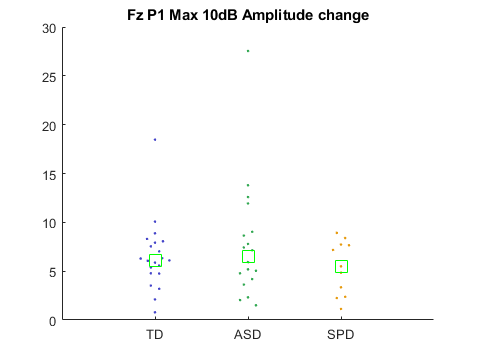

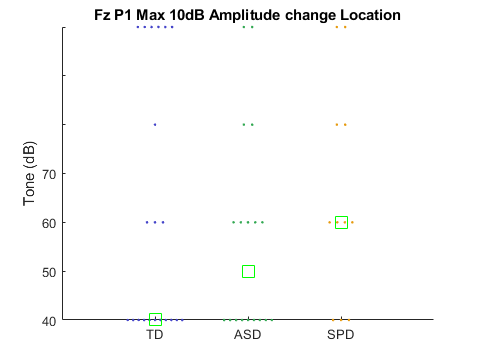

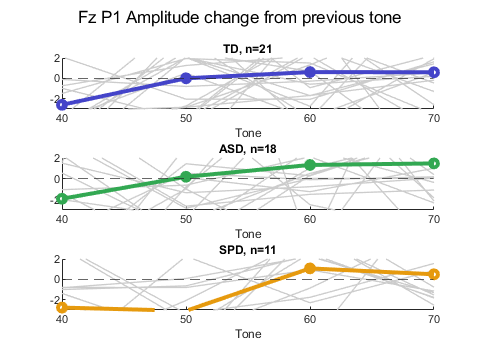

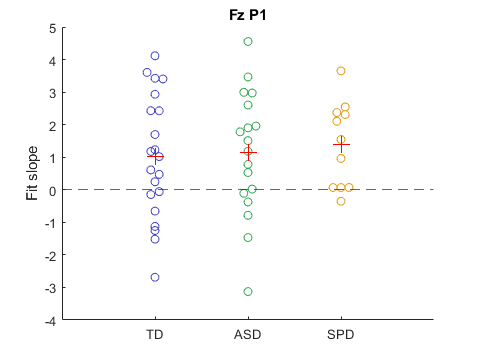

stats = 1×3 struct array with fields:
    TD_n
    ASD_n
    SPD_n
    feature
    p_MW_TD_ASD
    p_t_TD_ASD
    p_MW_SPD_ASD
    p_t_SPD_ASD

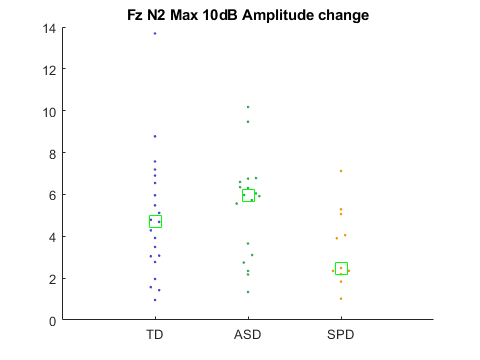

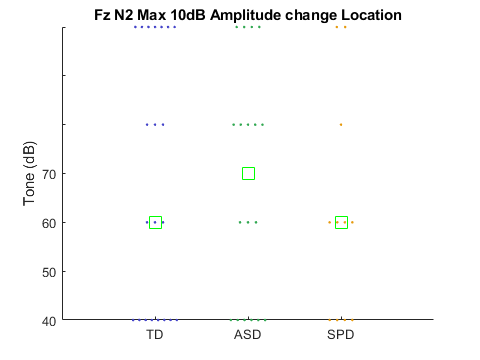

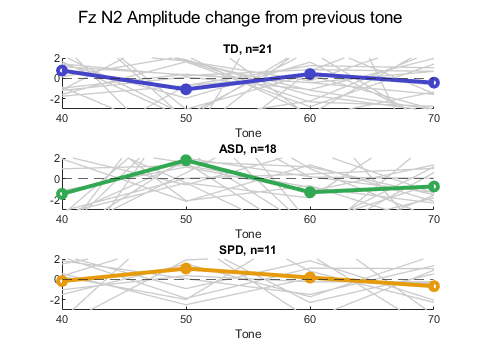

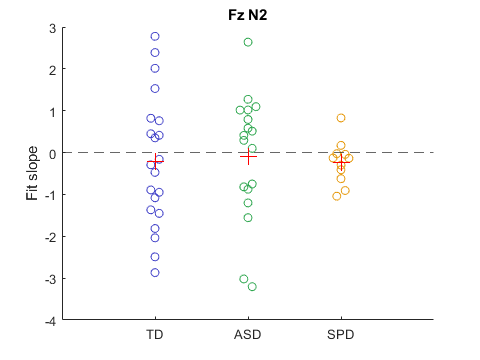

stats = 1×3 struct array with fields:
    TD_n
    ASD_n
    SPD_n
    feature
    p_MW_TD_ASD
    p_t_TD_ASD
    p_MW_SPD_ASD
    p_t_SPD_ASD

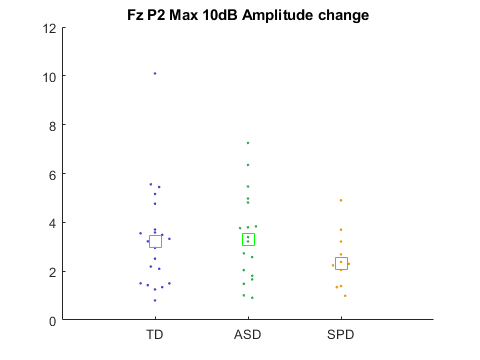

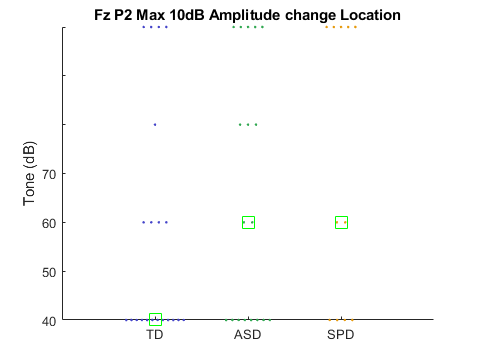

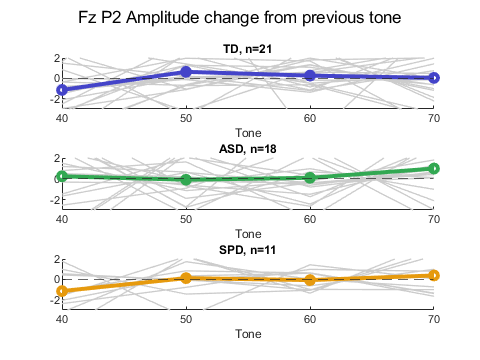

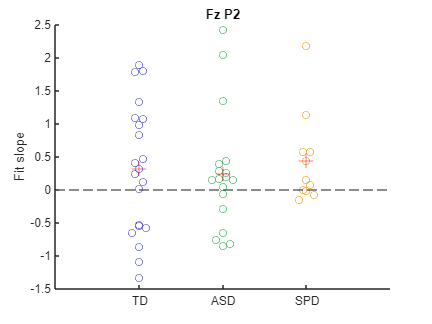

stats = 1×3 struct array with fields:
    TD_n
    ASD_n
    SPD_n
    feature
    p_MW_TD_ASD
    p_t_TD_ASD
    p_MW_SPD_ASD
    p_t_SPD_ASD

%% plot data by group
n_grps = length(groups); 
n_rois = length(rois);
n_erps = length(erps);
% iterate through ERP components
for i_e = 1:n_erps
    erp = erps{i_e};
    % iterate through ROIs
    for i_r = 1:n_rois
        roi = rois{i_r};
        % skip if ERP not in ROI
        if ~isfield(data.(roi),erp), continue; end
        % get all data from ERP component
        erp_data = data.(roi).(erp);
        % initialize structs to store group data
        grp_jump = cell(1,n_grps); 
        grp_i = grp_jump; grp_all = grp_jump;
        % iterate through groups
        for i_g = 1:n_grps
            % get all group data
            grp      = group_names{i_g};
            grp_data = erp_data([erp_data.group] == i_g);
            % save max amplitude jump, tone, and series of all jumps
            grp_jump{i_g} = [grp_data.max_jump];
            grp_i{i_g}    = [grp_data.max_jump_i];
            grp_all{i_g}  = [grp_data.all_jumps];
            % remove outliers, if selected
            if rm_outliers
                outliers = abs(zscore(grp_jump{i_g}))>2.6;
                grp_jump{i_g}(outliers) = [];
                grp_i{i_g}(outliers) = [];
                grp_all{i_g}(:,outliers) = [];
            end
            % save group n to stat table
            stats(1).([grp '_n']) = length(grp_jump{i_g});
        end
    
        %% plot max amplitude jump
        figure
        plotSpread(grp_jump,'distributionColors',colors(groups),'showMM',3)
        plot_title = plaintext( [roi ' ' erp ' Max 10dB Amplitude ' method] );
        title(plot_title)
        xticks(groups), xticklabels(group_names(groups))
        % run stats
        stats(1).feature = ['Max_Amplitude_' method];
        [stats(1).p_MW_TD_ASD,~,~] = ranksum(grp_jump{1},grp_jump{2},'tail','both');
        [~,stats(1).p_t_TD_ASD] = ttest2(grp_jump{1},grp_jump{2});
        [stats(1).p_MW_SPD_ASD,~,~] = ranksum(grp_jump{3},grp_jump{2},'tail','both');
        [~,stats(1).p_t_SPD_ASD] = ttest2(grp_jump{3},grp_jump{2});

        %% plot tone of max amplitude jump
        figure
        plotSpread(grp_i,'distributionColors',colors(groups),'showMM',3)
        title( [plot_title ' Location'] )
        xticks(groups), xticklabels(group_names(groups))
        ylabel('Tone (dB)')
        if ~isempty(conds)
            ta = tone_amps(2:end);
            yticklabels(ta(conds))
        else
            yticklabels(tone_amps)
        end
        % run stats
        stats(2).feature = ['Max_Amp_' method '_Tone'];
        [stats(2).p_MW_TD_ASD,~,~] = ranksum(grp_i{1},grp_i{2},'tail','both');
        [~,stats(2).p_t_TD_ASD] = ttest2(grp_i{1},grp_i{2});
        [stats(2).p_MW_SPD_ASD,~,~] = ranksum(grp_i{3},grp_i{2},'tail','both');
        [~,stats(2).p_t_SPD_ASD] = ttest2(grp_i{3},grp_i{2});
        
        %% plot amplitude changes from previous by tone
        figure, hold on
        for i_g = 1:n_grps
            ax(i_g) = subplot(n_grps,1,i_g); hold on
            grp = group_names{i_g};
            title([grp ', n=' int2str(stats(1).([grp '_n']))])
            plot(grp_all{i_g},'Color','#ccc','LineWidth',1)
            plot(mean(grp_all{i_g},2),'-o','Color',colors{i_g},'LineWidth',3)
            yline(0,'--')
            xticks(1:16), xticklabels(tone_amps(2:end)), xlabel('Tone')
        end
        linkaxes(ax), xlim(xlims), ylim([-3 2])
        sgtitle([roi ' ' erp ' Amplitude change from previous tone'])
        
        %% fit function to data
        coeffs = cell(1,n_grps);
        n_cond = length(conds);
        for i_g = groups
            n_subj = size(grp_all{i_g},2);
            for i_s = 1:n_subj
                x = 1:n_cond; y = grp_all{i_g}(conds,i_s);
                s_c = polyfit(x,y,1);
                coeffs{i_g}(i_s) = s_c(1);
            end
        end
        % plot slopes
        figure
        plotSpread(coeffs,'showMM',2,'distributionColors',colors,'distributionMarkers','o')
        yline(0,'--'), ylabel('Fit slope'), title([roi ' ' erp])
        xticks(groups), xticklabels(group_names)
        % add to stats table
        stats(3).feature = 'Fit_slope';
        stats(3).p_MW_TD_ASD = ranksum(coeffs{1},coeffs{2});
        [~,stats(3).p_t_TD_ASD] = ttest2(coeffs{1},coeffs{2});
        stats(3).p_MW_SPD_ASD = ranksum(coeffs{2},coeffs{3});
        [~,stats(3).p_t_SPD_ASD] = ttest2(coeffs{2},coeffs{3});

        %% display stats table
        stats
    end
end